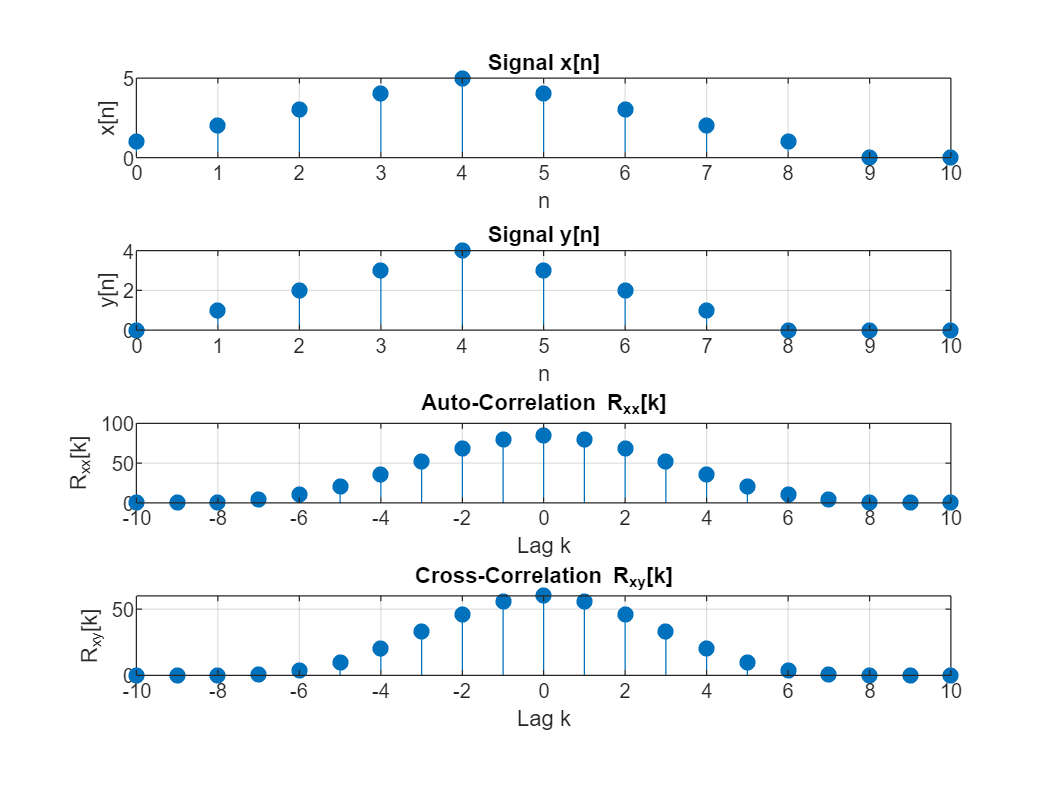

% Define the time vector
n = 0:10;

% Define two signals
x = [1, 2, 3, 4, 5, 4, 3, 2, 1, 0, 0];   % Signal x[n]
y = [0, 1, 2, 3, 4, 3, 2, 1, 0, 0, 0];   % Signal y[n]

% Compute auto-correlation of x[n]
R_xx = xcorr(x);

% Compute cross-correlation between x[n] and y[n]
R_xy = xcorr(x, y);

% Define the lag vector for plotting
lags = -(length(x)-1):(length(x)-1);

% Plot the signals
figure;

% Plot the original signal x[n]
subplot(4, 1, 1);
stem(n, x, 'filled');
title('Signal x[n]');
xlabel('n');
ylabel('x[n]');
grid on;

% Plot the original signal y[n]
subplot(4, 1, 2);
stem(n, y, 'filled');
title('Signal y[n]');
xlabel('n');
ylabel('y[n]');
grid on;

% Plot auto-correlation
subplot(4, 1, 3);
stem(lags, R_xx, 'filled');
title('Auto-Correlation R_{xx}[k]');
xlabel('Lag k');
ylabel('R_{xx}[k]');
grid on;

% Plot cross-correlation
subplot(4, 1, 4);
stem(lags, R_xy, 'filled');
title('Cross-Correlation R_{xy}[k]');
xlabel('Lag k');
ylabel('R_{xy}[k]');
grid on;


% Display the correlation results
disp('Auto-Correlation R_{xx}[k]:');

Auto-Correlation R_{xx}[k]:


disp(R_xx);

   -0.0000         0    1.0000    4.0000   10.0000   20.0000   35.0000   52.0000   68.0000   80.0000   85.0000   80.0000   68.0000   52.0000   35.0000   20.0000   10.0000    4.0000    1.0000   -0.0000   -0.0000




disp('Cross-Correlation R_{xy}[k]:');

Cross-Correlation R_{xy}[k]:


disp(R_xy);

    0.0000    0.0000    0.0000    1.0000    4.0000   10.0000   20.0000   33.0000   46.0000   56.0000   60.0000   56.0000   46.0000   33.0000   20.0000   10.0000    4.0000    1.0000    0.0000    0.0000    0.0000

